# 测试(形状法)

clc
clear
close all
addpath("src\");

## 地火转移

### 参数

tof  = 506;     % days
p.g0   = 9.80665; % m/s^2
p.Isp  = 3000;    % s
p.Tmax = 0.4;     % N
p.m0   = 1000;    % kg
a_m  = 1.54067001; %AU
e_m  = 0.088373;
i_m  = 1.842622;   % deg
mu   = 132712440018; % km^3/s^2
AU   = 149597870.700; % km
a_e  = 1; % AU
e_e  = 0.0167;
p.mu = mu / AU^3;
tspan = 0.001 * 86400; % s
tf = tof * 86400; % s
t =  0 : tspan : tf;

### 初始轨道

r_e = [a_e * (1 + e_e), 0, 0]';
v_e = [0, sqrt(p.mu * (2 / norm(r_e) - 1 / a_e)), 0]';
[x_e, dx_e] = Cart2Cylin(r_e, v_e);
r_m = [a_m * (1 + e_m), 0, 0]';
v_m = [0, sqrt(p.mu * (2 / norm(r_m) - 1 / a_m)), 0]';
[x_m, dx_m] = Cart2Cylin(r_m, v_m);
[~, x_e] = ode45(@(t, x) CylinEq(t, x, 0, p), t, [x_e; dx_e]);
[~, x_m] = ode45(@(t, x) CylinEq(t, x, 0, p), t, [x_m; dx_m]);

### 形状法(HM, t)

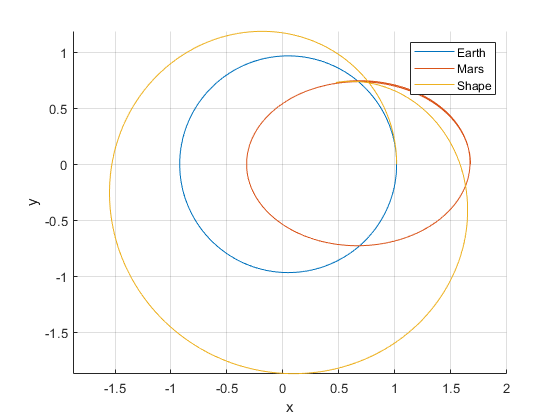

x0 = x_e(1, :)';
xf = x_m(end, :)';
[cr, cq, cz] = ShapeBaseHmT(x0, xf, tf);
tr = x0(1) + cr(1) * t + cr(2) * t.^2 / 2 + cr(3) * t.^3 / 3;
tz = x0(3) + cz(1) * t + cz(2) * t.^2 / 2 + cz(3) * t.^3 / 3;
tq = tr;
tq(1) = x0(2);
for i = 2 : length(tq)
    tq(i) = tq(i - 1) + tspan * (cq(1) + cq(2) * t(i - 1) + cq(3) * t(i - 1)^2) / tr(i - 1);
end
figure
hold on
plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
plot(tr .* cos(tq), tr .* sin(tq))
legend('Earth', 'Mars', 'Shape')
xlabel('x')
ylabel('y')
grid on
axis equal

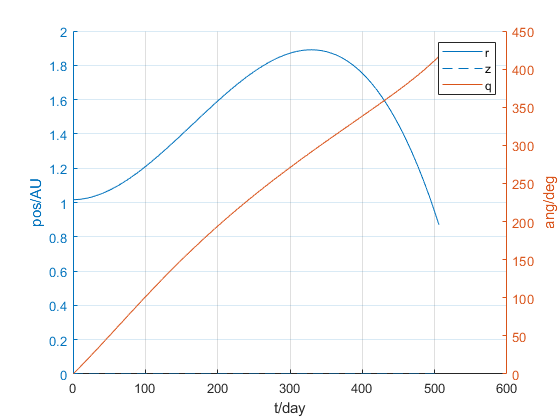

figure
hold on
xlabel('t/day')
yyaxis left
plot(t / 86400, [tr; tz])
ylabel('pos/AU')
yyaxis right
plot(t / 86400, tq * 180 / pi)
ylabel('ang/deg')
legend('r', 'z', 'q')
grid on

#### 验证修正推力

if false
    ta = [];
    tx = x0;
    for i = 2 : length(t)
        [A, B] = HmTSysCtrlMat(t(i), cr, cq, cz, x0, xf, p);
        ta = [ta B(4 : 6)];
        dx = CylinEq(0, tx(:, end), ta(:, end), p);
        tx = [tx tx(:, end) + tspan * dx];
    end
    figure
    hold on
    plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
    plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
    plot(tr .* cos(tq), tr .* sin(tq))
    plot(tx(1, :) .* cos(tx(2, :)), tx(1, :) .* sin(tx(2, :)))
    legend('Earth', 'Mars', 'Shape', 'Nom')
    xlabel('x')
    ylabel('y')
    grid on
    axis equal
end

FuncA = @(t) HmTSysCtrlMat(t, cr, cq, cz, x0, xf, p);
Phi0 = eye(12);
[~, PhiV] = ode45(@(t, x) StateTransEq(t, x, FuncA), t, Phi0);

Phi = Vec2Mat(PhiV(end, :), 12);

### 形状法(HM, theta)

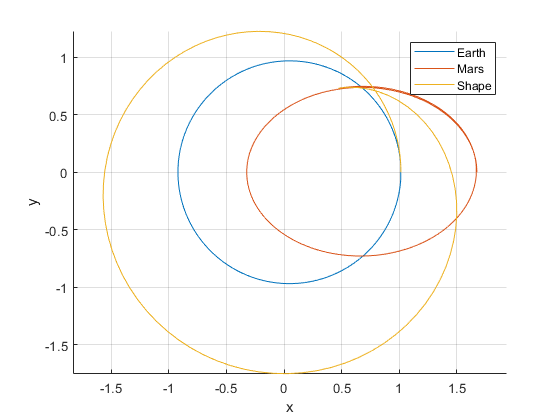

x0 = x_e(1, :)';
xf = x_m(end, :)';
[cr, ct, cz] = ShapeBaseHm(x0, xf, tf);
sspan = 0.01;
s = 0 : sspan : 1;
sq = x0(2) + s * (xf(2) - x0(2));
sr = x0(1) + cr(1) * s + cr(2) * s.^2 / 2 + cr(3) * s.^3 / 3;
st = ct(1) * s + ct(2) * s.^2 / 2 + ct(3) * s.^3 / 3;
sz = x0(3) + cz(1) * s + cz(2) * s.^2 / 2 + cz(3) * s.^3 / 3;
figure
hold on
plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
plot(sr .* cos(sq), sr .* sin(sq))
legend('Earth', 'Mars', 'Shape')
xlabel('x')
ylabel('y')
grid on
axis equal

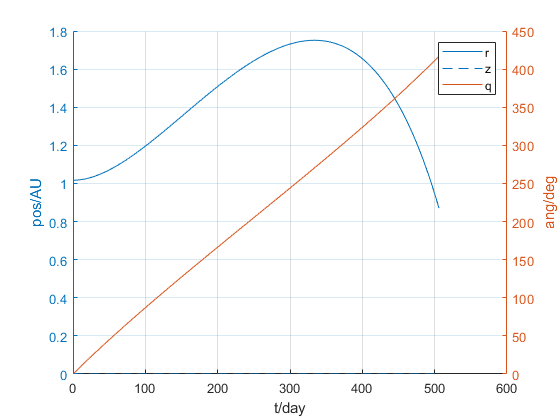

figure
hold on
xlabel('t/day')
yyaxis left
plot(st / 86400, [sr; sz])
ylabel('pos/AU')
yyaxis right
plot(st / 86400, sq * 180 / pi)
ylabel('ang/deg')
legend('r', 'z', 'q')
grid on

#### 验证修正推力(有误)

if false
    ta = [];
    tx = x0;
    for i = 1 : length(s)
        [A, B] = HmSysCtrlMat(s(i), cr, ct, cz, x0, xf, p);
        ta = [ta B(4 : 6) / (ct(1) + ct(2) * s(i) + ct(3) * s(i).^2)];
        tdx = CylinEq(0, tx(:, end), ta(:, end), p);
        tx = [tx tx(:, end) + sspan  * tdx * (ct(1) + ct(2) * s(i) + ct(3) * s(i).^2)];
    end
    figure
    hold on
    plot(x_e(:, 1) .* cos(x_e(:, 2)), x_e(:, 1) .* sin(x_e(:, 2)))
    plot(x_m(:, 1) .* cos(x_m(:, 2)), x_m(:, 1) .* sin(x_m(:, 2)))
    plot(sr .* cos(sq), sr .* sin(sq))
    plot(tx(1, :) .* cos(tx(2, :)), tx(1, :) .* sin(tx(2, :)))
    legend('Earth', 'Mars', 'Shape', 'Nom')
    xlabel('x')
    ylabel('y')
    grid on
    axis equal
end